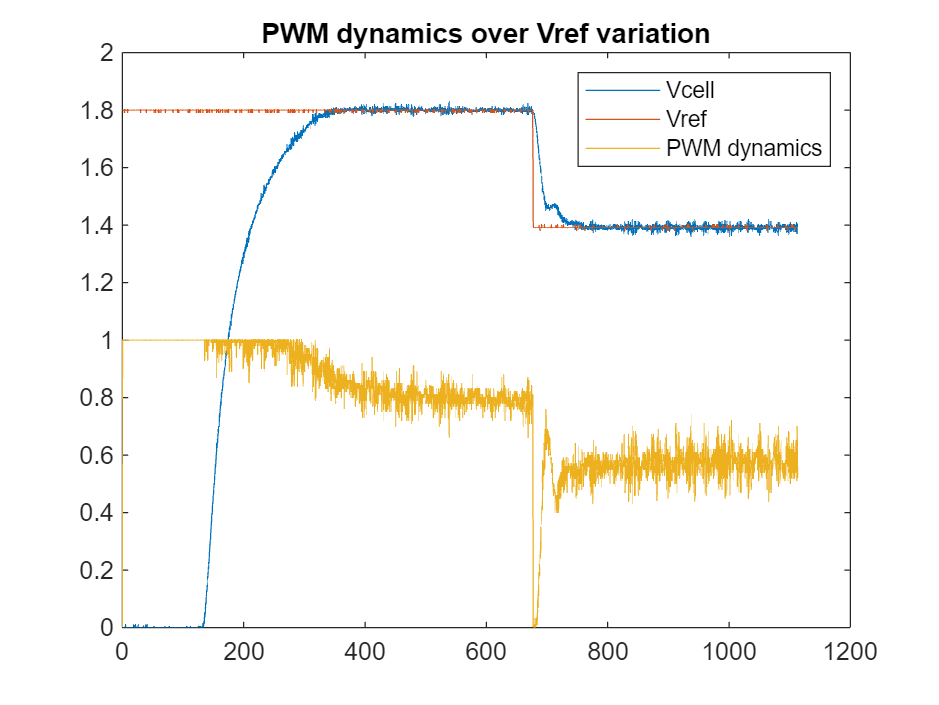

clear
close all
load acquisizione_controlCella.mat %acquisition with reference following and changing the reference with a potentiometer
Ts = 0.250;
Fs = 1/Ts;
setPoint1 =  1.8;
setPoint2 =  1.39;
t = 0:Ts:Ts*(length(data(:,1)) - 1);
ti1 = 0;
tf1 = 0; %a bunch of flags
ti2 = 0;
tf2 = 0;

figure

plot(t,data(:,2)')
hold on
plot(t,data(:,3)')
plot(t,data(:,1)')
legend("Vcell", "Vref", "PWM dynamics")
title("PWM dynamics over Vref variation")

A second order dynamic can be seen for the PWM. Note that the second order dynamic could have been seen also in the first rise but it is saturated to 1 so no upper obscillations

## Rise and Falling time calculation

for i=1:1:length(data(:,1))
    if (data(i,2) > 0.1*setPoint1 && ti1==0) %Check the time when the output goes over the 10% of the reference (if this time wasn't already checked)
        Ti1 = t(i);
        ti1 = 1;
    end
    if (data(i,2) > 0.9*setPoint1 && tf1==0)
        Tf1 = t(i);
        tf1 = 1;
    end
end

for i=2712:1:length(data(:,1))
    if (data(i,2) < setPoint1 - 0.1*(setPoint1 - setPoint2) && ti2==0) %output under the first setpoint of the 10% of the 'jump'
        Ti2 = t(i);
        ti2 = 1;
    end
    if (data(i,2) < setPoint1 - 0.9*(setPoint1 - setPoint2) && tf2==0)
        Tf2 = t(i);
        tf2 = 1;
    end
end

T_rise = Tf1 - Ti1

T_rise = 117.7500


T_fall = Tf2 - Ti2

T_fall = 40